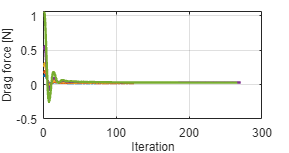

mean_drag = [];
cell_count = [148412, 166612, 229904, 478778, 1452627];


files = dir('data/drag-simulation/mesh-refinement/*.dat');

plotW = 8.5;
plotH = 4.5;

fig = figure('Color','w'); hold on
for j = 1:length(files)
    file = [files(j).folder '\' files(j).name];
    A = importdata(file, ' ', 4);
    t = A.data(:,1);
    drag_force = A.data(:,2);
    pressure_force = A.data(:,5);
    viscous_force = A.data(:,8);
    mean_drag(end+1) = mean(drag_force(end-20+1:end));
    plot(t,drag_force, 'LineWidth',2)
end
grid on; box on
xlabel('Iteration','Interpreter','tex')
ylabel('Drag force [N]','Interpreter','tex')
%legend('Refinement (3,4)','(4,5)','(5,6)','(6,7)','(7,8)','Orientation','horizontal','Location','northeast')

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'drag-convergence.pdf', '-dpdf', '-vector');

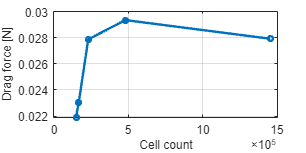


plotW = 9;
plotH = 4.5;

fig = figure('Color','w'); hold on

plot(cell_count,mean_drag,'Marker','o','MarkerSize',4,'LineWidth',2)

grid on; box on
xlabel('Cell count','Interpreter','tex')
ylabel('Drag force [N]','Interpreter','tex')

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'refinement-convergence.pdf', '-dpdf', '-vector');

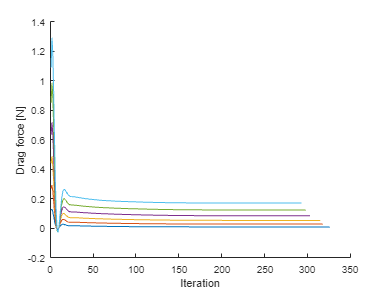

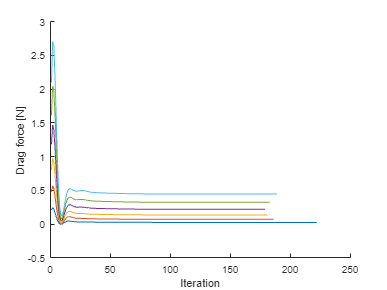

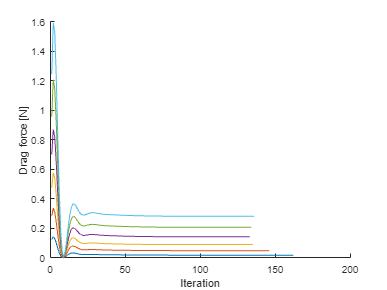

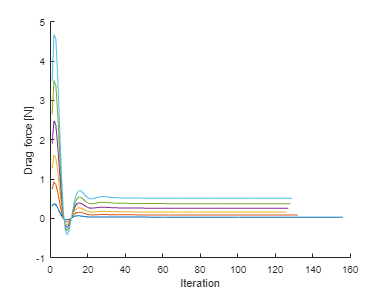

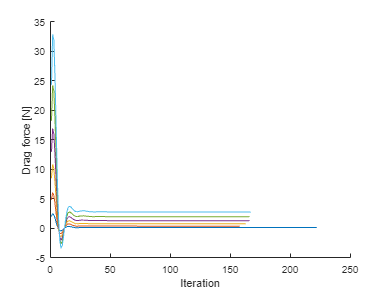

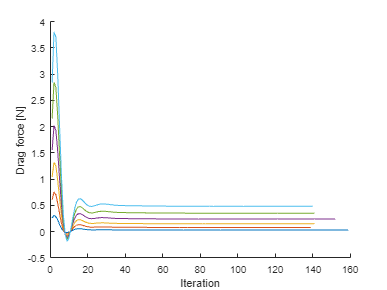

root = 'data/drag-simulation/';
finType = {'eel'; 'trout'; 'mackerel'; 'tuna'; 'boxfish'; 'average'};

mean_drag = [];

for i = 1:length(finType)
    files = dir([root finType{i} '/*.dat']);
    figure;
    hold on
    for j = 1:length(files)
        file = [files(j).folder '\' files(j).name];
        A = importdata(file, ' ', 4);
        t = A.data(:,1);
        drag_force = A.data(:,2);
        pressure_force = A.data(:,5);
        viscous_force = A.data(:,8);
        mean_drag(i,j) = mean(drag_force(end-20+1:end));
        mean_pressure(i,j) = mean(pressure_force(end-20+1:end));
        mean_viscous(i,j) = mean(viscous_force(end-20+1:end));
        plot(t,drag_force)
    end
    xlabel('Iteration')
    ylabel('Drag force [N]')
    hold off
end

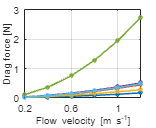

speeds = [0.2 0.4 0.6 0.8 1.0 1.2];

plotW = 5.5;
plotH = 4.5;

fig = figure('Color','w'); hold on
plot(speeds,mean_drag(1,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag(2,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag(3,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag(4,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag(5,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag(6,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)

grid on; box on
xlabel('Flow velocity [m s^{-1}]','Interpreter','tex')
ylabel('Drag force [N]','Interpreter','tex')
xlim([0.2 1.2])
xticks([0.2 0.6 1])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'drag-force.pdf', '-dpdf', '-vector');

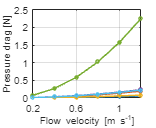


fig = figure('Color','w'); hold on
plot(speeds,mean_pressure(1,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_pressure(2,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_pressure(3,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_pressure(4,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_pressure(5,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_pressure(6,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)

grid on; box on
xlabel('Flow velocity [m s^{-1}]','Interpreter','tex')
ylabel('Pressure drag [N]','Interpreter','tex')
xlim([0.2 1.2])
xticks([0.2 0.6 1])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'pressure-drag-force.pdf', '-dpdf', '-vector');

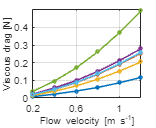


fig = figure('Color','w'); hold on
plot(speeds,mean_viscous(1,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_viscous(2,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_viscous(3,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_viscous(4,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_viscous(5,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_viscous(6,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)

grid on; box on
xlabel('Flow velocity [m s^{-1}]','Interpreter','tex')
ylabel('Viscous drag [N]','Interpreter','tex')
xlim([0.2 1.2])
xticks([0.2 0.6 1])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'viscous-drag-force.pdf', '-dpdf', '-vector');

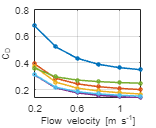

frontal_areas = [6.799289163579691e-04, 0.003113665752381, 0.002352462636663, 0.005173265027930, 0.015411799964259, 0.004465201580644];

rho = 1000;

mean_drag_coeff = [];
v2 = speeds'.^2;
for i=1:6
    for j=1:6
    mean_drag_coeff(i,j) = mean_drag(i,j)*2/rho/frontal_areas(i)/v2(j);
    end
end

fig = figure('Color','w'); hold on

plot(speeds,mean_drag_coeff(1,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag_coeff(2,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag_coeff(3,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag_coeff(4,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag_coeff(5,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)
plot(speeds,mean_drag_coeff(6,:),"LineWidth",1.5,"Marker","o","MarkerSize",3)

grid on; box on
xlabel('Flow velocity [m s^{-1}]','Interpreter','tex')
ylabel('C_{D}','Interpreter','tex')
xlim([0.2 1.2])
xticks([0.2 0.6 1])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'drag-coef.pdf', '-dpdf', '-vector');

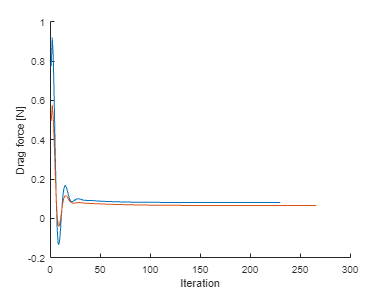

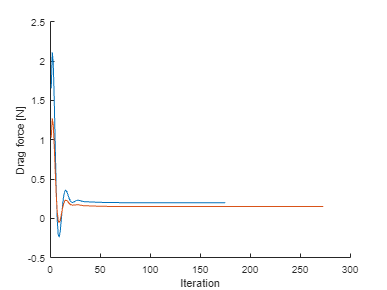

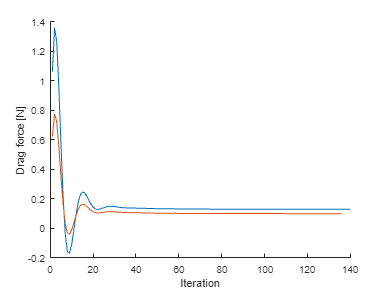

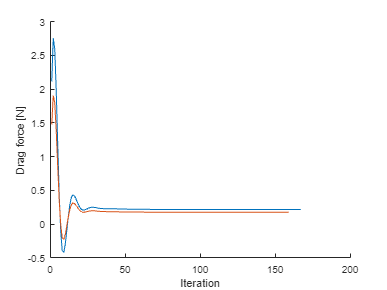

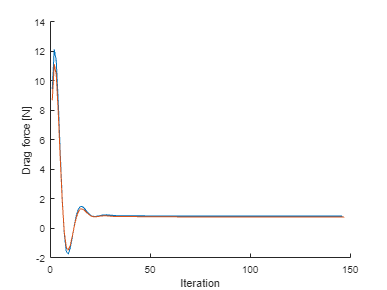

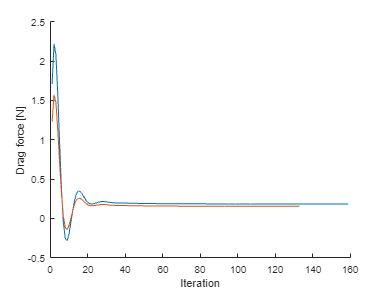

root = 'data/drag-simulation/';
finType = {'eel'; 'trout'; 'mackerel'; 'tuna'; 'boxfish'; 'average'};

mean_drag_off_axis = [];
mean_side_force = [];

for i = 1:length(finType)
    files = dir([root finType{i} '/off-axis' '/*.dat']);
    figure;
    hold on
    for j = 1:length(files)
        file = [files(j).folder '\' files(j).name];
        A = importdata(file, ' ', 4);
        t = A.data(:,1);
        drag_force = A.data(:,2);
        side_force = A.data(:,4);
        pressure_force = A.data(:,5);
        viscous_force = A.data(:,8);
        mean_drag_off_axis(i,j) = mean(drag_force(end-20+1:end));
        mean_pressure_off_axis(i,j) = mean(pressure_force(end-20+1:end));
        mean_viscous_off_axis(i,j) = mean(viscous_force(end-20+1:end));
        mean_side_force(i,j) = mean(side_force(end-20+1:end));
        plot(t,drag_force)
    end
    xlabel('Iteration')
    ylabel('Drag force [N]')
    hold off
end

mean_drag_off_axis_all = [mean_drag(:,3) flip(mean_drag_off_axis,2)]

mean_drag_off_axis_all =     0.0532    0.0661    0.0813
    0.1359    0.1505    0.1990
    0.0894    0.0993    0.1287
    0.1625    0.1751    0.2142
    0.7530    0.7696    0.8268
    0.1476    0.1555    0.1842



mean_side_force_correct = flip(mean_side_force,2)

mean_side_force_correct =     0.0215    0.0517
    0.1492    0.3501
    0.0981    0.2173
    0.1549    0.3259
    0.1683    0.3668
    0.1007    0.2095



mean_viscous_off_axis_all = [mean_viscous(:,3) flip(mean_viscous_off_axis,2)]

mean_viscous_off_axis_all =     0.0386    0.0491    0.0565
    0.0863    0.0885    0.0923
    0.0679    0.0703    0.0727
    0.0988    0.0991    0.0994
    0.1702    0.1726    0.1762
    0.0879    0.0886    0.0899



mean_pressure_off_axis_all = [mean_pressure(:,3) flip(mean_pressure_off_axis,2)]

mean_pressure_off_axis_all =     0.0147    0.0170    0.0248
    0.0496    0.0621    0.1067
    0.0215    0.0290    0.0560
    0.0637    0.0760    0.1148
    0.5828    0.5970    0.6507
    0.0597    0.0670    0.0943



off_axis_percentage = 100*(mean_drag_off_axis_all - mean_drag_off_axis_all(:,1))./mean_drag_off_axis_all(:,1)

off_axis_percentage =          0   24.0818   52.6213
         0   10.7832   46.4479
         0   11.0687   44.0299
         0    7.7860   31.8394
         0    2.2033    9.8060
         0    5.3805   24.7865


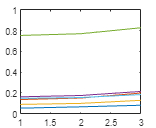


plot(mean_drag_off_axis_all')

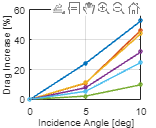

fig = figure('Color','w'); hold on
plot([0, 5, 10], off_axis_percentage',"LineWidth",1.5,"Marker","o","MarkerSize",3)
grid on; box on
xlabel('Incidence Angle [deg]','Interpreter','tex')
ylabel('Drag Increase [%]','Interpreter','tex')
xlim([0 10])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'off-axis-drag.pdf', '-dpdf', '-vector');

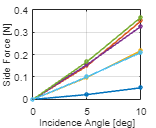

fig = figure('Color','w'); hold on
plot([0 5 10], [zeros(1,6); abs(mean_side_force_correct')],"LineWidth",1.5,"Marker","o","MarkerSize",3)
grid on; box on
xlabel('Incidence Angle [deg]','Interpreter','tex')
ylabel('Side Force [N]','Interpreter','tex')
xlim([0 10])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'side-force.pdf', '-dpdf', '-vector');

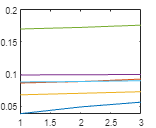

plot(mean_viscous_off_axis_all')

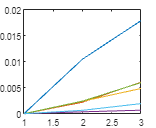

plot((mean_viscous_off_axis_all - mean_viscous_off_axis_all(:,1))')

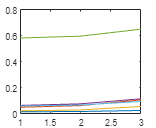

plot(mean_pressure_off_axis_all')

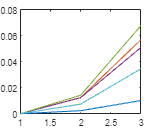

plot((mean_pressure_off_axis_all - mean_pressure_off_axis_all(:,1))')